# Parsing der Json Dateien für Fahrzeugparameter

## NL Intercity VIRM6

Beispiel für ein neues Fahrzeug, bei welchem die Parameter von einem json-File importiert werden. Folgende Einheiten müssen dabei eingehalten werden:

- Masse (mass): Tonnen

- Achslast (M_axle): Tonnen

- Anz. angetriebene Achsen (N_axles): (-)

- Übergangsgeschwindigkeit (v_start): km/h (muss Üblicherweise berechnet werden)

- Max. Geschwindigkeit (maxSpeed): km/h

- Anz. Wagen (N_waggon): (-)

- Max. Beschleunigung (maxAcceleration): m/s^2

- Max. Bremsbeschleunigung (maxDeceleration): m/s^2

- Drehmassenzuschlagsfaktor (rho): (-)

- Max. Dauerleistung am Rad (P_cont): kW

- Max. Leistung am Rad (maxTractionPower): kW

- Max. regenerative Leistung (maxRegPower): kW

- Anfahrtszugkraf (maxTractionForce): kN

- Bremskraft (maxPnBreakingForce): kN

- Haftwert/Reibungswert/Adhäsionskoeffizient (mu_break): (-)

- Min. Geschwindigkeit für regeneratives Bremsen (minSpeedRegBraking): km/h

Da die Einheiten im json-File nicht alle den benötigten Einheiten entsprechen wurden diese nachfolgend noch geändert. Dies muss bei jedem neuen Fahrzeug individuell betrachtet werden.

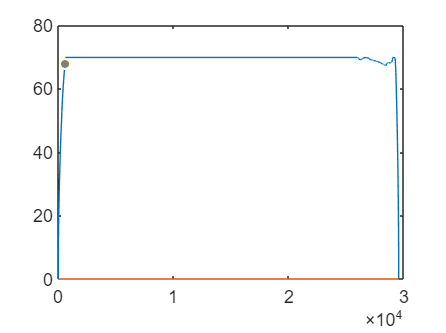

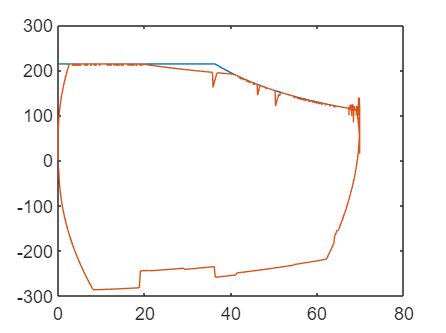

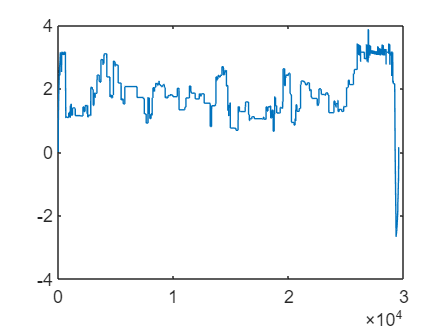

NL_Intercity_VIRM6 = jsondecode(char((fread(fopen('NL_Intercity_VIRM6.json'),inf))'));
NL_Intercity_VIRM6.mass = NL_Intercity_VIRM6.mass/1000;
NL_Intercity_VIRM6.maxTractionPower = NL_Intercity_VIRM6.maxTractionPower/1000;
NL_Intercity_VIRM6.maxTractionForce = NL_Intercity_VIRM6.maxTractionForce/1000;
NL_Intercity_VIRM6.maxPnBrakingForce = NL_Intercity_VIRM6.maxPnBrakingForce/1000;
NL_Intercity_VIRM6.maxDeceleration = NL_Intercity_VIRM6.maxDeceleration * (-1);
NL_Intercity_VIRM6.maxRegPower = NL_Intercity_VIRM6.maxRegPower/1000;

% Bei fehlenden Angaben müssen die Parameter ergänzt werden z.Bsp.:
NL_Intercity_VIRM6.maxAcceleration = 0.8; % (m/s)


## mögliche neue Fahrzeuge:

Hier können die neuen Fahrzeuge importiert werden, gleich wie im vorhergehenden Beispiel mit dem NL_Intercity_VIRM6. Die Einheiten müssen immer eingehalten und bei Bedarf angepasst werden (Beispiel oben)

ff =      1     2     3     4     5     6     7     8     9    10
